# Repeat Reunion Part 8: SvC Huddling 

## 0. Create huddling table and check distributions

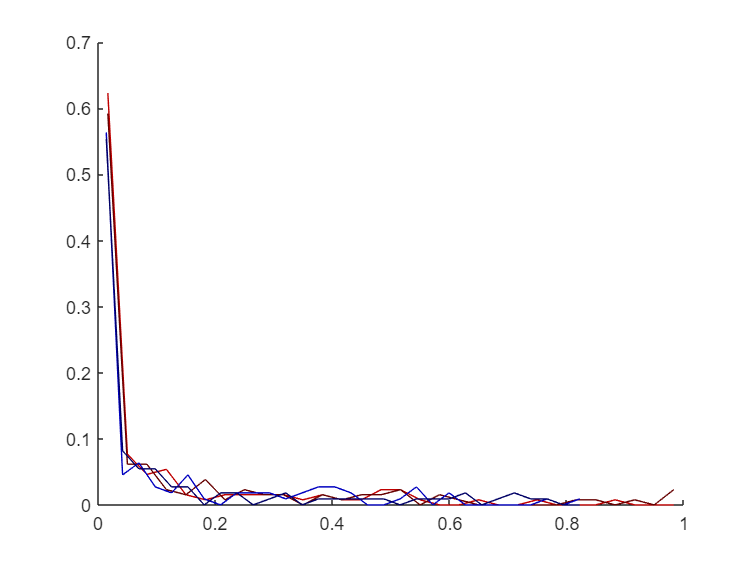

colorcodes_fem = [    0.7500         0         0; ...
    0.4000         0         0 ; ...
    1.0000    0.3500    0.3500];

colorcodes_mal = [         0         0    0.7500;...
         0         0    0.4000;...
    0.3500    0.3500    1.0000];


sbG = reun_mksumbehav3(rdb_rr, 4);
degutableHf = Make_DeguTable3(rdb_rr, fem_ind, sbG, 1, 1);
degutableHm = Make_DeguTable3(rdb_rr, mal_ind, sbG, 1, 1);

[a b] = hist(reshape(degutableHf(:,6:17,1), [],1), 30);
[aSf bSf] = hist(reshape(degutableHf(:,11:15), [], 1), b);
[aCf bCf] = hist(reshape(degutableHf(:,6:10), [], 1), b);

[a b] = hist(reshape(degutableHm(:,6:17,1), [],1), 30);
[aSm bSm] = hist(reshape(degutableHm(:,11:15), [], 1), b);
[aCm bCm] = hist(reshape(degutableHm(:,6:10), [], 1), b);

figure
hold on
plot(bSf, aSf/sum(aSf), 'Color', colorcodes_fem(1,:));
plot(bCf, aCf/sum(aSf), 'Color', colorcodes_fem(2,:));
box off

plot(bSm, aSm/sum(aSm), 'Color', colorcodes_mal(1,:));
plot(bCm, aCm/sum(aSm), 'Color', colorcodes_mal(2,:));

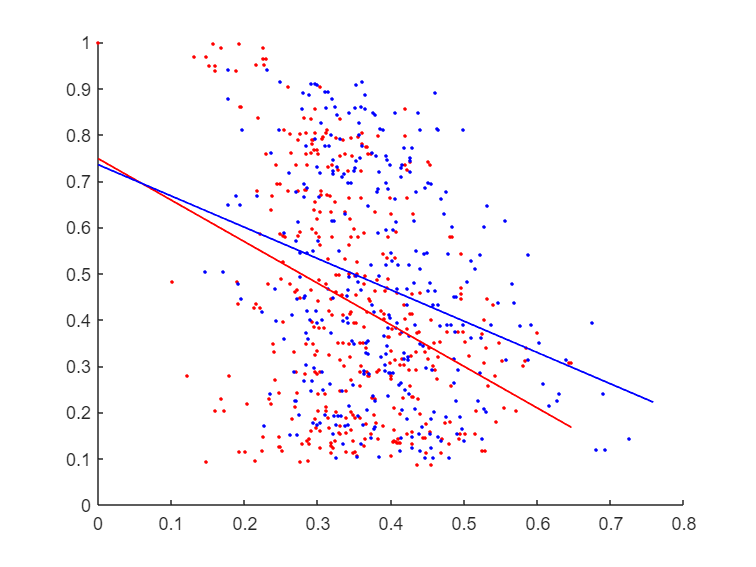


%plot(bS, aS, 'Color', colorcodes_fem(3,:));
dtt = sum(degutable,3);
dttM = sum(degutableM,3);

allHm = reshape(degutableHm(:,6:17).^(1/3), [], 1);
allHf = reshape(degutableHf(:,6:17).^(1/3), [], 1);
allDT = reshape(dtt(:,6:17).^(1/3), [], 1);
allDTM = reshape(dttM(:,6:17).^(1/3), [], 1);


notnanHf = find(allHf > 0 & ~isnan(allDT));
notnanHm = find(allHm > 0 & ~isnan(allDTM));


figure
plot(allDT(notnanHf), allHf(notnanHf), 'r.');
hold on
plot(allDTM(notnanHm), allHm(notnanHm), 'b.');
box off



pF = polyfit(allDT(notnanHf), allHf(notnanHf), 1);
pFx = [min(allDT) max(allDT)];
pFy = polyval(pF, pFx);
plot(pFx, pFy, 'Color', 'r', 'LineWidth', 1);

pM = polyfit(allDTM(notnanHm), allHm(notnanHm), 1);
pMx = [min(allDTM) max(allDTM)];
pMy = polyval(pM, pMx);
plot(pMx, pMy, 'Color', 'b', 'LineWidth', 1);





[a b] = corr(allDT(notnanHf), allHf(notnanHf))

a = -0.3570

b = 3.1453e-13


[a b] = corr(allDTM(notnanHm), allHm(notnanHm))

a = -0.2831

b = 2.3832e-07

## I. Levels of huddling and changes over sessions


dtt = degutableHf;
dttM = degutableHm;


figure
sp1 = subplot(1,5,1:3)

sp1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.4494 0.8150]
            Units: 'normalized'

  Show all properties


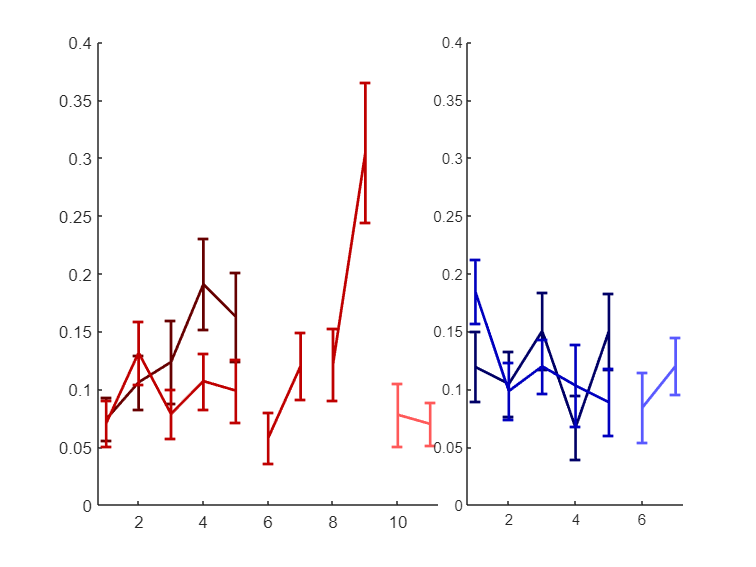

%sp1 = subplot(1,2,1); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES
hold on

% randselect = randperm(size(dtt,1), 10);
% for i = 1:length(randselect)
%     plot(1:5, dtt(randselect(i), 6:10), 'Color', [1 .90 .90], 'LineStyle', '--');        
% 
%     plot(1:5, dtt(randselect(i), 11:15), 'Color', [1 .90 .90]);
% 
% %    plot(1:5, dtt(randselect(i), 16:20), 'Color', [1 .95 .90], 'LineStyle', ':');
% end

errorbar(1:5,nanmean(dtt(:, 6:10)), nanstd(dtt(:, 6:10))./sqrt(sum(~isnan(dtt(:,6:10)))), 'Color', colorcodes_fem(2,:), 'LineWidth', 1.5);
errorbar(1:5,nanmean(dtt(:, 11:15)), nanstd(dtt(:, 11:15))./sqrt(sum(~isnan(dtt(:,11:15)))), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5 );
errorbar(6:7, nanmean(dtt(:,21:22)), nanstd(dtt(:, 21:22))./sqrt(sum(~isnan(dtt(:,21:22)))), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5); %COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
errorbar(8:9, nanmean(dtt(:,23:24)), nanstd(dtt(:, 23:24))./sqrt(sum(~isnan(dtt(:,23:24)))), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5);%COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
errorbar(10:11,nanmean(dtt(:, 16:17)), nanstd(dtt(:, 16:17))./sqrt(sum(~isnan(dtt(:,16:17)))), 'Color', colorcodes_fem(3,:), 'LineWidth', 1.5 );%COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
set(sp1, 'XLim', [.75 11.25]); 
box off
%set(sp1, 'XLim', [.75 11.25]); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES


sp2 = subplot(1,5,4:5);
%sp2 = subplot(1,2,1); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES
hold on

% randselect = randperm(size(dttM,1), 10);
% for i = 1:length(randselect)
%     plot(1:5, dttM(randselect(i), 6:10), 'Color', [.90 .90 1], 'LineStyle', '--');        
% 
%     plot(1:5, dttM(randselect(i), 11:15), 'Color', [.90 .90 1]);
% 
%  %   plot(1:5, dttM(randselect(i), 16:20), 'Color', [.9 .95 1], 'LineStyle', ':');
% end


errorbar(1:5,nanmean(dttM(:, 6:10)), nanstd(dttM(:, 6:10))./sqrt(sum(~isnan(dttM(:,6:10)))), 'Color', colorcodes_mal(2,:), 'LineWidth', 1.5);
errorbar(1:5,nanmean(dttM(:, 11:15)), nanstd(dttM(:, 11:15))./sqrt(sum(~isnan(dttM(:,11:15)))), 'Color', colorcodes_mal(1,:), 'LineWidth', 1.5 );
errorbar(6:7,nanmean(dttM(:, 16:17)), nanstd(dttM(:, 16:17))./sqrt(sum(~isnan(dttM(:,16:17)))), 'Color', colorcodes_mal(3,:), 'LineWidth', 1.5 );%COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES

box off
set(sp2, 'XLim', [.75 7.25]); %COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
%set(sp2, 'XLim', [.75 5.25]); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES
ylim1 = get(sp1, 'YLim');
ylim2 = get(sp2, 'YLim');
maxlims = max([ylim1 ; ylim2]);
set(sp1, 'YLim', [0 maxlims(2)-.0]);
set(sp2, 'YLim', [0 maxlims(2)-.0]);

Stats

allbyday_f = cat(3,dtt(:,6:10), dtt(:,11:15));
allbyday_m = cat(3,dttM(:,6:10), dttM(:,11:15));
allbyday_ct = [allbyday_f ; allbyday_m].^(1/3);
allbyday_ct_notransform = [allbyday_f ; allbyday_m];
femmalvec = [ones(size(allbyday_f,1),1) ; 2*ones(size(allbyday_m,1),1)];

%[tbl,rm] = simple_mixed_anova(allbyday_ct, femmalvec, {'exposureday' 'cagstr'}, {'sex'})


y_abd = reshape(allbyday_ct_notransform, [], 1,1);
y_abdN0 = y_abd;
y_abdN0(y_abdN0 == 0) = 0.0001;
y_abdCR = y_abd.^(1/3);

% Linearize the matrices
lin_sex = reshape(repmat(femmalvec-1, 5, 2), [], 1, 1);
strcag = cat(3, zeros(size(allbyday_ct,1), size(allbyday_ct,2)), ones(size(allbyday_ct,1), size(allbyday_ct,2)));
lin_strcag = reshape(strcag, [], 1, 1);
lin_days = reshape(repmat(1:5, size(allbyday_ct, 1), size(allbyday_ct,3)), [],1,1);
degunum = repmat([1:size(allbyday_ct,1)]', 1, size(allbyday_ct, 2), size(allbyday_ct,3));
lin_degunum = reshape(degunum, [], 1, 1);

%create table
abd_T = table(lin_degunum, lin_days, lin_strcag, lin_sex, y_abd, y_abdN0, y_abdCR, lin_degunum_STR);

% Run the model
%glme_CR = fitglme(abd_T, 'y_abdCR ~ 1 + lin_strcag + lin_sex + lin_days + lin_strcag:lin_sex + lin_strcag:lin_days + lin_sex:lin_days + lin_strcag:lin_sex:lin_days + (1 | lin_degunum)')
glme_CRs = fitglme(abd_T, 'y_abdCR ~ 1 + lin_strcag + lin_sex + lin_days + lin_strcag:lin_sex + lin_strcag:lin_days + lin_sex:lin_days + lin_strcag:lin_sex:lin_days + (1 | lin_degunum_STR)');
[~, ~, stats_all] = fixedEffects(glme_CRs)

stats_all =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                                   Estimate     SE          tStat      DF     pValue       Lower         Upper    
    {'(Intercept)'                }          0.23393    0.041989     5.5713    952    3.291e-08       0.15153      0.31633
    {'lin_days'                   }         0.021904    0.011629     1.8837    952     0.059915    -0.0009163     0.044725
    {'lin_strcag'                 }         0.042608    0.054543    0.78119    952      0.43488     -0.064429      0.14965
    {'lin_sex'                    }         0.074416    0.062022     1.1998    952       0.2305       -0.0473      0.19613
    {'lin_days:lin_strcag'        }          -0.0226    0.016445    -1.3743    952      0.16968     -0.054873    0.0096729
    {'lin_days:lin_sex'           }        -0.025883    0.017176    -1.5069    952      0.13217     -0.059591    0.0078252
    {'lin_strcag:lin_sex'         }       

## II. Comparing huddling across individuals

SC-HIGH vs. SC-LOW


j = 1

j = 1

%for j = 1:2
    if j == 1
        dttT = dtt;
        indsigT = indsig;
        indnonsigT = indnonsig;
    else
        dttT = dttM;
        indsigT = indsigM;
        indnonsigT = indnonsigM;
    end

    allbyday = [dttT(indsigT, 6:10) ; dtt(indsigT, 11:15)].^(1/3);
    daymat = repmat(1:5, length(indsigT)*2, 1);
    dyadmat = repmat(1:length(indsigT)', 2, 5);
    cagVstr = [zeros(size(indsigT,1), 5) ; ones(length(indsigT), 5)];

    y_abd = reshape(allbyday, [],1);
    lin_days = reshape(daymat, [], 1);
    lin_degunum = reshape(dyadmat, [],1);
    lin_strcag  = reshape(cagVstr, [],1);

    abd_T_S = table(lin_degunum, lin_days, lin_strcag, y_abd);
    glme_S = fitglme(abd_T_S, 'y_abd ~ 1 + lin_strcag + lin_days + lin_strcag:lin_days + (1 | lin_degunum)');
    [~, ~, stats_S{j}] = fixedEffects(glme_S);
    stats_S{j}

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE          tStat      DF     pValue       Lower        Upper   
    {'(Intercept)'        }          0.26072     0.08026     3.2484    156    0.0014213      0.10218     0.41925
    {'lin_days'           }         0.028177    0.021371     1.3185    156      0.18928    -0.014037    0.070391
    {'lin_strcag'         }         0.099981     0.11351    0.88085    156      0.37975     -0.12422     0.32419
    {'lin_days:lin_strcag'}        -0.049642    0.030223    -1.6425    156       0.1025     -0.10934    0.010058



    %[B, BINT, R, RINT, STATS] = regress(anovacell{1}, [ones(length(anovacell{1}),1) anovacell{2} anovacell{4} anovacell{2}.*anovacell{4}]);
    %B
    %BINT

    abd2 = cat(3,dttT(indsigT, 6:10) , dttT(indsigT, 11:15)).^(1/3);

    fprintf('sig -- sex: %d', j)

sig -- sex: 1

    tbl = simple_mixed_anova(abd2, [], {'exposureday' 'cagstr'})

tbl = 8×8 table
                                       SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    __    ________    _______    __________    __________    __________    __________

    (Intercept)                         16.464     1      16.464     80.148    2.0986e-07    2.0986e-07    2.0986e-07    2.0986e-07
    Error                               3.0812    15     0.20541                                                                   
    (Intercept):exposureday            0.16942     4    0.042355    0.61739       0.65182       0.61501       0.65182       0.44426




    allbyday = [dttT(indnonsigT, 6:10) ; dtt(indnonsigT, 11:15)].^(1/3);
    daymat = repmat(1:5, length(indnonsigT)*2, 1);
    dyadmat = repmat(1:length(indnonsigT)', 2, 5);
    cagVstr = [zeros(size(indnonsigT,1), 5) ; ones(length(indnonsigT), 5)];

    y_abd = reshape(allbyday, [],1);
    lin_days = reshape(daymat, [], 1);
    lin_degunum = reshape(dyadmat, [],1);
    lin_strcag = reshape(cagVstr, [],1);

    abd_T_NS = table(lin_degunum, lin_days, lin_strcag, y_abd);
    glme_NS = fitglme(abd_T_NS, 'y_abd ~ 1 + lin_strcag + lin_days + lin_strcag:lin_days + (1 | lin_degunum)');
    [~, ~, stats_NS{j}] = fixedEffects(glme_NS);
    stats_NS{j}

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE          tStat      DF     pValue       Lower         Upper   
    {'(Intercept)'        }          0.22203    0.053579      4.144    356    4.269e-05       0.11666      0.3274
    {'lin_days'           }         0.019116    0.014046      1.361    356      0.17439    -0.0085078     0.04674
    {'lin_strcag'         }         0.017109    0.075772     0.2258    356      0.82148      -0.13191     0.16613
    {'lin_days:lin_strcag'}        -0.010582    0.019864    -0.5327    356      0.59457     -0.049648    0.028484




    abd2 = cat(3,dttT(indnonsigT, 6:10) , dttT(indnonsigT, 11:15)).^(1/3);
    fprintf('nonsig -- sex: %d', j)

nonsig -- sex: 1

    tbl = simple_mixed_anova(abd2, [], {'exposurday' 'cagstr'})

tbl = 8×8 table
                                      SumSq      DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                                     ________    ___    ________    ______    __________    __________    __________    __________

    (Intercept)                        26.646      1      26.646    113.25    1.6236e-12    1.6236e-12    1.6236e-12    1.6236e-12
    Error                              8.2349     35     0.23528                                                                  
    (Intercept):exposurday            0.50083      4     0.12521    1.8418       0.12418       0.14154       0.13456       0.18343
    <


%end

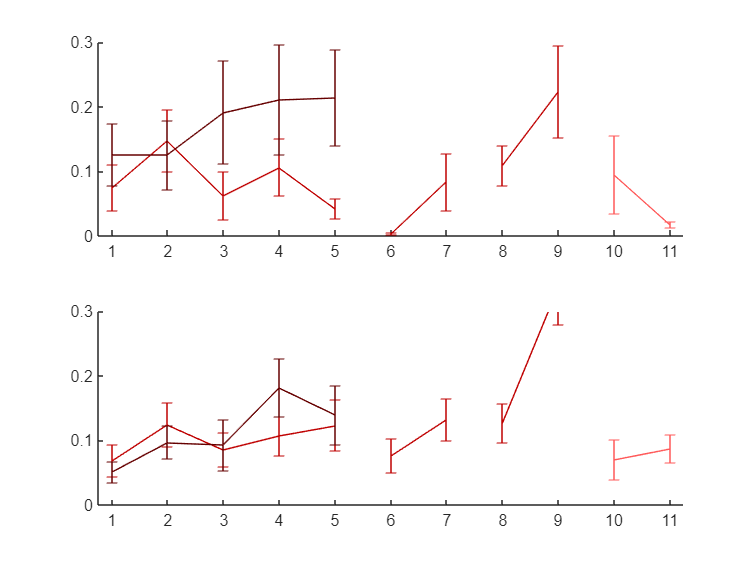

figure
subplot(2,1,1)
e1 = errorbar(1:5, nanmean(dtt(indsig,11:15)), nanstd(dtt(indsig,11:15))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indsig,6:10)), nanstd(dtt(indsig,6:10))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(10:11, nanmean(dtt(indsig,16:17)), nanstd(dtt(indsig,16:17))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(3,:))

%e1 = errorbar(1:5, nanmean(dttM(indsigM,11:15)), nanstd(dttM(indsigM,11:15))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
%e2 = errorbar(1:5, nanmean(dttM(indsigM,6:10)), nanstd(dttM(indsigM,6:10))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

%errorbar(1:2, nanmean(dttM(indsigM,16:17)), nanstd(dttM(indsigM,16:17))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(3,:))

errorbar(6:7, nanmean(dtt(indsig,21:22)), nanstd(dtt(indsig, 21:22)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indsig,23:24)), nanstd(dtt(indsig, 23:24)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));

set(get(e1, 'parent'), 'XLim', [0.75 11.25])
ylims = get(get(e1, 'parent'), 'YLim');
box off
subplot(2,1,2)
e1 = errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(10:11, nanmean(dtt(indnonsig,16:17)), nanstd(dtt(indnonsig,16:17))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(3,:))

%e1 = errorbar(1:5, nanmean(dttM(indnonsigM,11:15)), nanstd(dttM(indnonsigM,11:15))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(1,:));
%hold on

%e2 = errorbar(1:5, nanmean(dttM(indnonsigM,6:10)), nanstd(dttM(indnonsigM,6:10))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(2,:));


%errorbar(1:2, nanmean(dttM(indnonsigM,16:17)), nanstd(dttM(indnonsigM,16:17))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(3,:))



errorbar(6:7, nanmean(dtt(indnonsig,21:22)), nanstd(dtt(indnonsig, 21:22)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indnonsig,23:24)), nanstd(dtt(indnonsig, 23:24)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
set(get(e1, 'parent'), 'XLim', [0.75 11.25])
set(get(e1, 'parent'), 'YLim', ylims);
box off